# DEMO of Multi-color superpixel method. 

This web is to demonstrate the multi-color superpixel method published in our [paper](https://opg.optica.org/oe/fulltext.cfm?uri=oe-31-14-22649&id=532168#articleReferences)

(Note that the program cannot run before you re-generate the DLUT in your own computer, since the DLUT is too large and cannot be uploaded to github. )

## 1. Define target Field

the target fields here are plane waves in different colors. 

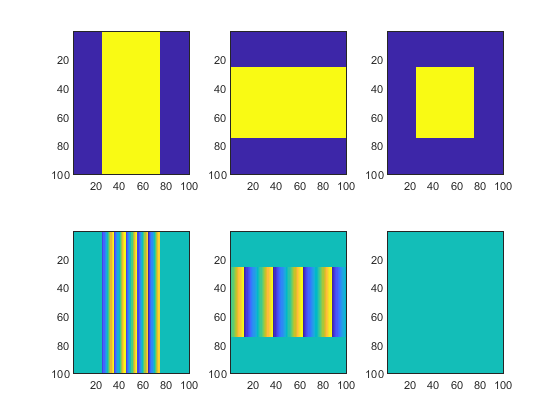

% Define the field. 
N=100; %number of superpixels. 
Utar=zeros(N,N,3);
[X,Y]=meshgrid(1:N,1:N); % grid

Utar(:,:,1)=8*exp(1i*2*pi/10*X).*(abs(X-N/2)<N/4);
Utar(:,:,2)=8*exp(1i*2*pi/25*X).*(abs(Y-N/2)<N/4);
Utar(:,:,3)=8*(abs(Y-N/2)<N/4).*(abs(X-N/2)<N/4);

figure
for i=1:3
    subplot(2,3,i)
    imagesc(abs(Utar(:,:,i)).^2) %Intensity
    subplot(2,3,3+i)
    imagesc(angle(Utar(:,:,i))) %Phase
end

## 2. Generate DMD pattern

Load the DLUT and then use "DMDgeneration_SP" function. 

The DLUT is already generated. If you want to generate DLUT with different parameters (e.g. wavelength), you may refer to the 4th part. 

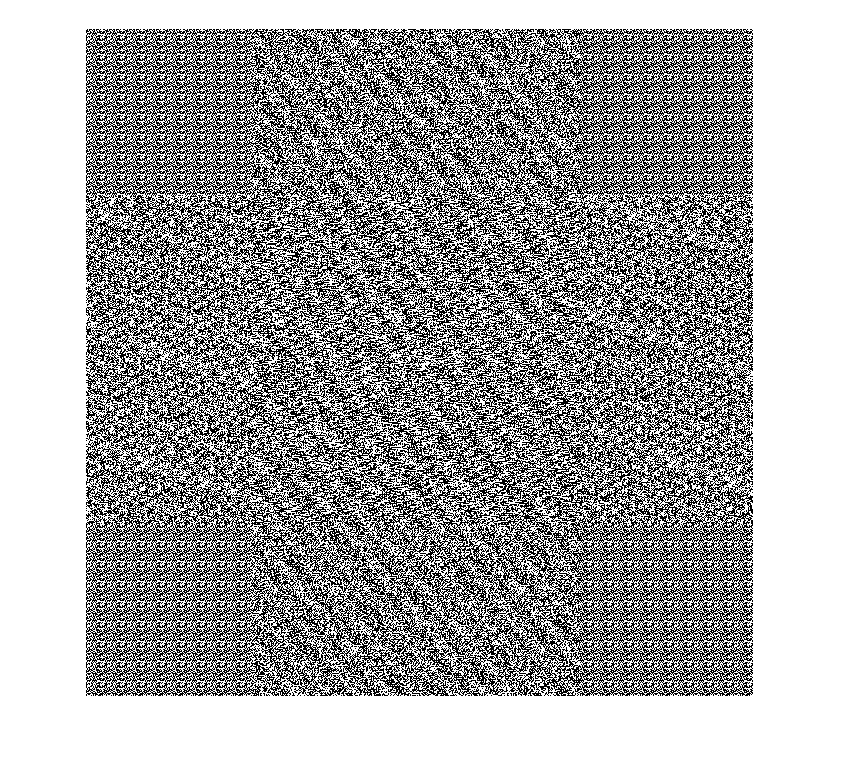

%load DLUT
mfLUT=matfile("DLUT/LUT-3.mat");
mfKDT=matfile("DLUT/KDTmodel-3.mat");
%
[DMD_SP,Error]=DMDgeneration_SP(Utar,mfLUT.wavelength,mfLUT.wavelength0,mfLUT.Npx,mfKDT.model,mfLUT.spList);

figure
imshow(DMD_SP)

This pattern is not with the same size of DMD in general, you may padding "0" or "1" to adjust the size. But in simulation, that is not important. 

## 3. Simulation

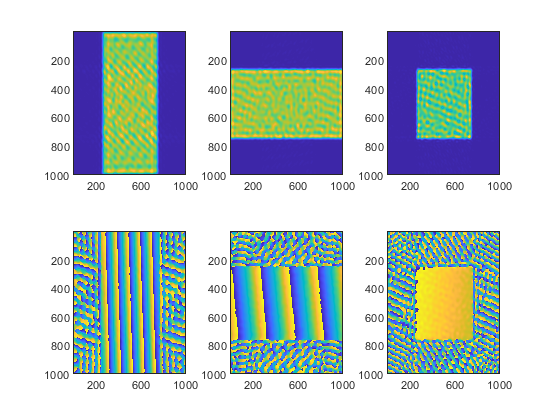


%simulate the output image
um=1e-6;
mm=1e-3;
px_size=7.56*um;
wavelength=um.*mfLUT.wavelength;
wavelength0=mfLUT.wavelength0*um;
Npx=mfLUT.Npx;
focal_len=250*mm;
a=wavelength0*focal_len/(Npx^2*px_size);
R=a*0.6;
npad=30*Npx; %padding to avoid reflection of borders in Fresnel diffraction simulation. 
DMD_SP=Padding(DMD_SP,npad);
Uout_SP=DMDforvard(DMD_SP,px_size,wavelength,Npx,a,R,focal_len);
Uout_SP=InvPadding(Uout_SP,npad);
DMD_SP=InvPadding(DMD_SP,npad);

figure
for i=1:3
    subplot(2,3,i)
    imagesc(abs(Uout_SP(:,:,i)).^2) %Intensity
    subplot(2,3,3+i)
    imagesc(angle(Uout_SP(:,:,i))) %Phase
end

## 4. DLUT generation

You can find two codes in folder "DLUT". 

"LUTgenerate.m" generate the DLUT, you may modify the parameters and run the program. Then use "save("DLUT-x")"  to save data to "DLUT-x.mat". Note that the generation of DLUT may take long time, depending on your parameters. You may want to choose small Ba and Bp as test (Ba~1,Bp~2). 

"KDTgenerate.m" generate the KDTree based on the input DLUT filename. You also need save it as "KDTmodel-x.mat".  

After generating the new DLUT and KDTmodel files, you can load them as in part 2. 